# Husky Localisation using LiDAR in Unstructured Environments

Kamryn Norton 

References: [https://www.mathworks.com/help/vision/ug/build-a-map-from-lidar-data-using-slam.html](https://www.mathworks.com/help/vision/ug/build-a-map-from-lidar-data-using-slam.html) 

                     [https://www.mathworks.com/help/lidar/ug/build-a-map-and-localise-using-segment-matching.html](https://www.mathworks.com/help/lidar/ug/build-a-map-and-localize-using-segment-matching.html) 

### Process files in the directory into pointCloud objects and put them in a table with their file names

dataFolder = "HuskyLiDAR_Data";
%can be '.ply' or '.pcd' files
pointCloudFilePattern = fullfile(dataFolder, 'lasers', 'laser_mesh*.ply');
plyFiles = dir(pointCloudFilePattern); %get list of directory

Error encountered: files were in lexical order. Extract the numeric part of the file names:

fileNumbers = cellfun(@(x) sscanf(x, 'laser_mesh%d.ply'), {plyFiles.name});
% Sort the indices based on the extracted numbers
[~, sortedIndices] = sort(fileNumbers);
% Apply the sorted indices to plyFiles to get them in the correct order
plyFiles = plyFiles(sortedIndices);

Instatiate & populate cell arrays to store data for the table containing point cloud data. 

numFiles = length(plyFiles);
fileNames = cell(numFiles, 1);
pointClouds = cell(numFiles, 1);

%Loops through the ply files and read them
for k = 1:length(plyFiles)
    plyFilename = fullfile(plyFiles(k).folder, plyFiles(k).name);
    pc = pcread(plyFilename);
    % Store the file name and point cloud in the cell arrays
    fileNames{k} = plyFiles(k).name;
    pointClouds{k} = pc;
end
cloudDataTable = table(fileNames, pointClouds, 'VariableNames', {'FileName', 'PointCloud'})

cloudDataTable = 1032×2 table
          FileName             PointCloud   
    ____________________    ________________

    {'laser_mesh0.ply' }    {1×1 pointCloud}
    {'laser_mesh1.ply' }    {1×1 pointCloud}
    {'laser_mesh2.ply' }    {1×1 pointCloud}
    {'laser_mesh3.ply' }    {1×1 pointCloud}
    {'laser_mesh4.ply' }    {1×1 pointCloud}
    {'laser_mesh5.ply' }    {1×1 pointCloud}
    {'laser_mesh6.ply' }    {1×1 pointCloud}
    {'laser_mesh7.ply' }    {1×1 pointCloud}
    {'laser_mesh8.ply' }    {1×1 pointCloud}
    {'laser_mesh9.ply' }    {1×1 pointCloud}
    {'laser_mesh10.ply'}    {1×1 pointCloud}
    {'laser_mesh11.ply'}    {1×1 pointCloud}
    {'laser_mesh12.ply'}    {1×1 pointCloud}
    {'laser_mesh13.ply'}    {1×1 pointCloud}
    {'laser_mesh14.ply'}    {1×1 pointCloud}
    {'laser_mesh15.ply'}    {1×1 pointCloud}


#### Instantiate Processing Parameters

dsPercent = 0.5; %downsamplePercent
regGridSize = 1.5; %changed from 3 to 1.5 

% Set the cylinder radius and ego radius
cylinderRadius = 40;
egoRadius = 1;
numExpectedFiles =475; %one data set has 451 clouds (indoor3) 

%segmentation params
minNumPoints = 100;
distThreshold = 1;
angleThreshold = 180;

## SegMatch Map Building

### Create Map & Localisation Sets 

% Select a subset of point cloud scans, and split the data to use for map building and for localisation.
ptCloudMap = vertcat(pointClouds{1:2:numExpectedFiles-20}); 
ptCloudLoc = vertcat(pointClouds{2:2:numExpectedFiles-20}); %have to use vertcat because it is pcd data
%every 2nd odd cloud is map, every 2nd even cloud is localisation
ptCloudMapLabels = fileNames(1:2:numExpectedFiles-10);
ptCloudLocLabels = fileNames(2:2:numExpectedFiles-10);

Initial Transform

currentViewId = 2;

%Pre-processing
prevPtCloud = PreProcess(ptCloudMap(currentViewId-1), ...
    egoRadius,cylinderRadius);
ptCloud = PreProcess(ptCloudMap(currentViewId), ...
    egoRadius,cylinderRadius);

prevPtCloudDS = pcdownsample(prevPtCloud,'random',dsPercent);
ptCloudDS = pcdownsample(ptCloud,'random',dsPercent);

Register & find inital transformation

gridStep = 1.5; %size of voxels
relPose = pcregisterndt(ptCloudDS,prevPtCloudDS,gridStep);
locations =[0 0 0]; %to store map locations for analysis
 
vSet2 = pcviewset;
%initialise pose to an identity grid transformation
initAbsPose = rigidtform3d;

vSet2 = addView(vSet2,currentViewId-1,initAbsPose); %add to view
% absolute pose of the second point cloud using the relative pose estimated during registration
absPose2 = rigidtform3d(initAbsPose.A * relPose.A);
locations = vertcat(locations,absPose2.Translation); %for analysis
vSet2 = addView(vSet2,currentViewId,absPose2); %add it to the view set.
%connect the 2 views
vSet2 = addConnection(vSet2,currentViewId-1,currentViewId,relPose);
%transform current pcloud to align to global map
ptCloud = pctransform(ptCloud,absPose2);

### Segment point cloud and extract features: straight from example 

prevPtCloud = organise(prevPtCloud);
ptCloud = organise(ptCloud);

%Segment the previous and current point clouds using segmentLidarData.
labels1 = segmentLidarData(prevPtCloud,distThreshold,angleThreshold, ...
    'NumClusterPoints',minNumPoints);
labels2 = segmentLidarData(ptCloud,distThreshold,angleThreshold, ...
    'NumClusterPoints',minNumPoints);
%Extract features from the previous and current point cloud segments using extractEigenFeatures.
[prevFeatures,prevSegments] = extractEigenFeatures(prevPtCloud,labels1);
[features,segments] = extractEigenFeatures(ptCloud,labels2);
%Track the segments and features using a pcmapsegmatch object. Create an empty pcmapsegmatch.
segMap = pcmapsegmatch;
segMap = addView(segMap,currentViewId-1,prevFeatures,prevSegments); %previous features and segments added to pcmapsegmatch
segMap = addView(segMap,currentViewId,features,segments); %current features and segments added

### Detect loop closures using findPose

[absPoseMap,loopClosureViewId] = findPose(segMap,absPose2);
isLoopClosure = ~isempty(absPoseMap);
%set the absolute pose of the current view without the accumulated drift, absPoseMap, and the absolute pose of the loop 
%closure view, absPoseLoop, to compute the relative pose between the loop closure poses without the drift.
if isLoopClosure
    absPoseLoop = poses(vSet2,loopClosureViewId).AbsolutePose;
    relPoseLoopToCurrent = rigidtform3d(invert(absPoseLoop).A * absPoseMap.A);
    %Add the loop closure relative to the pose as a connection using addConnection.
    vSet2 = addConnection(vSet2,loopClosureViewId,currentViewId, ...
    relPoseLoopToCurrent);    

    prevPoses = vSet2.Views.AbsolutePose;

    %create a posegraph from the view & optimise
    G2 = createPoseGraph(vSet2);     
    optimG2 = optimizePoseGraph(G2,'g2o-levenberg-marquardt');
    vSet2 = updateView(vSet2,optimG2.Nodes);

    %find the transformations from the poses before + after drift correction 
    optimizedPoses2 = vSet2.Views.AbsolutePose;
    
    relPoseOpt = rigidtform3d.empty;
    for k = 1:numel(prevPoses)
        relPoseOpt(k) = rigidtform3d(optimizedPoses2(k).A * invert(prevPoses(k)).A);
    end
    
    segMap = updateMap(segMap,relPoseOpt); %updating the map segments & centroid locations
end

Build map and correct for accumulated drift error - applied to the rest of the scans

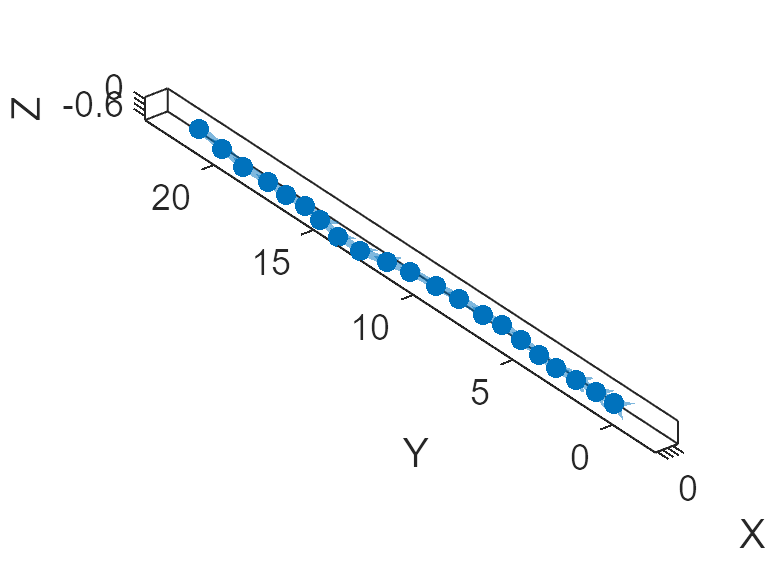

% Set the random seed for example reproducibility.
rng(0)

% Update display every 2 scans
figure
updateRate = 2;

% Initialize variables for registration.
prevPtCloud = ptCloudDS;
prevPose = rigidtform3d;

% Keep track of the loop closures to optimize the poses once enough loop closures are detected.
totalLoopClosures = 0;
tic; %timing for analysis

for i = 3:numel(ptCloudMap)
    ptCloud = ptCloudMap(i);
    % Preprocess and register the point cloud.
    ptCloud = PreProcess(ptCloud,egoRadius,cylinderRadius);
    ptCloudDS = pcdownsample(ptCloud,'random',dsPercent); %changed from Voxel downsampling
    relPose = pcregisterndt(ptCloudDS,prevPtCloud,gridStep, ... %gridStep defined earlier =1.5
        'InitialTransform',relPose);   
    ptCloud = pctransform(ptCloud,absPose2);
    
    % Store the current point cloud to register the next point cloud.
    prevPtCloud = ptCloudDS;    
    
    % Compute the absolute pose of the current point cloud.
    absPose2 = rigidtform3d(absPose2.A * relPose.A);
    locations = vertcat(locations,absPose2.Translation); %add to array of locations 
    % If the vehicle has moved at least 1 meter since last time, continue through steps to loop closure detection.
    if norm(absPose2.Translation-prevPose.Translation) >= 1 %Changed to suit smaller data set, example was every 2m
        
        ptCloud = organise(ptCloud);
        % Segment the point cloud and extract features.
        labels = segmentLidarData(ptCloud,distThreshold,angleThreshold, ...
            'NumClusterPoints',minNumPoints);
        [features,segments] = extractEigenFeatures(ptCloud,labels);
        
        % Keep track of the current view id.
        currentViewId = currentViewId+1;

        % Fixing eigenvalue error (sometimes empty features)
        if ~isa(features, 'eigenFeature') && ~isempty(features)
                features = eig(features);
        end
        if isempty(features)
            [features,segments] = extractEigenFeatures(ptCloudMap(i-1));
        end

        % Add the view to the point cloud view set and map representation.
        vSet2 = addView(vSet2,currentViewId,absPose2);
        vSet2 = addConnection(vSet2,currentViewId-1,currentViewId, ...
            rigidtform3d(invert(prevPose).A * absPose2.A));
        segMap = addView(segMap,currentViewId,features,segments);
        
        % Update the view set display.
        if mod(currentViewId,updateRate) == 0
            plot(vSet2)
            drawnow
        end

        % Check if there is a loop closure.
        [absPoseMap,loopClosureViewId] = findPose(segMap,absPose2,'MatchThreshold',1, ...
            'MinNumInliers',5,'NumSelectedClusters',4,'NumExcludedViews',150);
        isLoopClosure = ~isempty(absPoseMap);
        
        if isLoopClosure
            totalLoopClosures = totalLoopClosures+1;
            
            % Find the relative pose between the loop closure poses.
            absPoseLoop = poses(vSet2,loopClosureViewId).AbsolutePose;
            relPoseLoopToCurrent = rigidtform3d(invert(absPoseLoop).A * absPoseMap.A);
            vSet2 = addConnection(vSet2,loopClosureViewId,currentViewId, ...
                relPoseLoopToCurrent);
            
            % Optimize the graph of poses and update the map every time 3
            % loop closures are detected.
            if mod(totalLoopClosures,3) == 0
                prevPoses = vSet2.Views.AbsolutePose;
                
                % Correct for accumulated drift: create and optimise pose graph
                G = createPoseGraph(vSet2);
                optimG = optimizePoseGraph(G,'g2o-levenberg-marquardt');
                vSet2 = updateView(vSet2,optimG.Nodes);
                
                % Find the transformations from the poses before and after correcting for drift 
                %and use them to update the map segments and centroid locations using updateMap.
                optimizedPoses2 = vSet2.Views.AbsolutePose;
                relPoseOpt = rigidtform3d.empty;
                for k = 1:numel(prevPoses)
                    relPoseOpt(k) = rigidtform3d(optimizedPoses2(k).A * invert(prevPoses(k)).A);
                end
                segMap = updateMap(segMap,relPoseOpt);
                
                % Update the absolute pose after pose graph optimization.
                absPose2 = optimizedPoses2(end);
            end
        end
        prevPose = absPose2; %for iterative registration through each scan
    end
end

timetobuildmap =toc; %for analysis

## Localise Vehicle in Known Map

Same preprocessing and segmentation for consistency. 

ptCloud = ptCloudMap(200);

% Preprocess the point cloud.
ptCloud = PreProcess(ptCloud,egoRadius,cylinderRadius);
ptCloud = organise(ptCloud);
% Segment the point cloud and extract features.  
labels = segmentLidarData(ptCloud,distThreshold,angleThreshold, ...
    'NumClusterPoints',minNumPoints);
features = extractEigenFeatures(ptCloud,labels);
 segMap = selectSubmap(segMap,[segMap.XLimits segMap.YLimits segMap.ZLimits]);

Use the [`findPose`](docid:lidar_ref#mw_5fc1ef80-253d-46ae-909b-1ca69b88aebd) object function of [`pcmapsegmatch`](docid:lidar_ref#mw_acc8abe2-15e0-4f27-a991-6cce7d217bc4) to localise the vehicle on the prebuilt map.

tic; %analysis
 absPoseMap = findPose(segMap,features,'MatchThreshold',30,'MinNumInliers',3) 

absPoseMap =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [0.3938 7.3203 -0.5205]
                 R: [3×3 single]
                 A: [4×4 single]


timeforsegmatch = toc %analysis

timeforsegmatch = 0.8660

Visualize the map. Visualize the vehicle on the map as a cuboid.

mapColor = [0 0.4 0.7];
mapSegments = pccat(segMap.Segments);

figure;
hAxLoc = pcshow(mapSegments.Location,mapColor); %plot(vSet2)
title('Localisation on a Prebuilt Map')
view(2)

poseTranslation = absPoseMap.Translation;
quat = quaternion(absPoseMap.Rotation','rotmat','point');
theta = eulerd(quat,'ZYX','point');
pos = [poseTranslation 1 1 1 theta(2) theta(3) theta(1)];
showShape('cuboid',pos,'Color','green',...%'Parent',hAxLoc, ...
    'Opacity',0.8,'LineWidth',0.5)

Removed the selection of a submap due to the small nature of the environment traversed. 

% Visualize the map.
figure('Visible','on')
hAx = plot(vSet2);%pcshow(mapSegments.Location,mapColor);

title('Localisation on a Prebuilt Map')

% Set parameter to update submap.
%submapThreshold = 20;
tic;
% Initialize the poses and previous point cloud for registration.
prevPtCloud = ptCloud;
relPose = rigidtform3d;
prevAbsPose = rigidtform3d;
localisedPoses = [0 0 0];
segMatchLocations = [0 0 0];
% Segment each point cloud and localise by finding segment matches in the map.
for n = 2:numel(ptCloudLoc)
    ptCloud = ptCloudLoc(n);

    % Preprocess the point cloud.
    ptCloud = PreProcess(ptCloud,egoRadius,cylinderRadius);
    ptCloud = organise(ptCloud);
    % Segment the point cloud and extract features.
    labels = segmentLidarData(ptCloud,distThreshold,angleThreshold, ...
        'NumClusterPoints',minNumPoints);
    features = extractEigenFeatures(ptCloud,labels);

    % localise the point cloud using SegMatch.
    smLoc = findPose(sMap,features,'MatchThreshold',30,'MinNumInliers',3);
    if isempty(smLoc)
        smLoc = [0 0 0];
        segMatchLocations = vertcat(segMatchLocations,smLoc);
    else
        segMatchLocations = vertcat(segMatchLocations,smLoc.Translation);
    end
   
    % Do registration localisation and analyse against SegMatch Locations above.
        relPose = pcregisterndt(ptCloud,prevPtCloud,gridStep, ...
            'InitialTransform',relPose);
        absPoseMap = rigidtform3d(prevAbsPose.A * relPose.A);
     
    localisedPoses = vertcat(localisedPoses, absPoseMap.Translation); %for analysis
    hold on; %to build the registration map on the pre-built map
    % Display position estimate in the map.
    poseTranslation = absPoseMap.Translation;
    quat = quaternion(absPoseMap.Rotation','rotmat','point');
    theta = eulerd(quat,'ZYX','point');
    pos = [poseTranslation 0.3 0.3 0.3 theta(2) theta(3) theta(1)];
    showShape('cuboid',pos,'Color','green',...%'Parent',hAx,
        'Opacity',0.4,'LineWidth',0.5)
    legend('Map', 'Location', 'best')

    %for iterative purposes:
    prevAbsPose = absPoseMap;
    prevPtCloud = ptCloud;
end

%hold off;
timeforregistration =toc;

#### ANALYSIS TOOLS

figure;
plot(locations,'LineWidth', 1.5)
hold on
plot(localisedPoses)
legend("X Map", "Y Map", "Z Map", "X Loc", "Y Loc", "Z Loc", 'Location','best')
title('NDT Registration Localisation Positions and Map Positions Over All Samples')
xlabel("Sample")
ylabel("Position (m)")
hold off
set(gca,"XGrid","off","YGrid","on")


%SegMatch Localisation vs Map
figure;
plot(segMatchLocations)
hold on
plot(locations, 'LineWidth', 2)
legend("X SM", "Y SM", "Z SM","X Map", "Y Map", "Z Map", 'Location','best')
title('SegMatch Localisation Positions and Map Positions Over All Samples')
xlabel("Sample")
ylabel("Position (m)")
hold off

%Final Error
xError = abs(locations(end-1,1)-localisedPoses(end,1))
yError = abs(locations(end-1,2)-localisedPoses(end,2))
zError = abs(locations(end-1,3)-localisedPoses(end,3))
barLabels= categorical({'X','Y','Z'});
barData = [xError yError zError];
clear bar;
figure;
bar(barLabels, barData, 0.2)
set(gca,"XGrid","off","YGrid","on")
grid minor
text(1:length(barData),barData,num2str(barData'),'vert','bottom','horiz','center'); 
title("Graph Showing the Final Error for Localisation")
xlabel("Coordinate")
ylabel("Final Error (m)")

%Distances
store = [];
outliers = [];
for i=1:numel(localisedPoses)
     temp = vecnorm(locations(i)- localisedPoses(i));
     if temp<10
        store(i) = temp;
     else 
         outliers(i) = temp; %remove large outliers
     end 
end
figure;
plot(store)
hold on;
hold off;
title("Distance Between Localised Point and Map Point")
xlabel("Sample")
ylabel("Distance (m)")

%Write times to spreadsheet to not lose them
filename = 'testData3.xlsx';
times = table(timetobuildmap, timeforregistration,timeforsegmatch);
writetable(times, filename, 'Sheet', 5, 'Range', 'A1');

Helper Functions

function ptCloudNoGround = PreProcess(ptCloud,egoRadius,cylinderRadius)

    % Select the points inside the cylinder radius and outside the ego radius.
    cylinderIdx = findPointsInCylinder(ptCloud,[egoRadius cylinderRadius]);
    ptCloud = select(ptCloud,cylinderIdx,'OutputSize','full');
    
    % Remove ground.
    [~,ptCloudNoGround] = segmentGroundSMRF(ptCloud,'ElevationThreshold',0.5);
    
    %return ptCloudNoGround;
end

function OrganisedPCloud = organise(ptCloud)
    %to organise the point cloud for the segmentations - WERE ISSUES HERE
    horizontalRes = 512; %channels in horizontal direc, 512 or 1024
    params = lidarParameters('VLP32C', horizontalRes);
    OrganisedPCloud = pcorganize(ptCloud,params);
end